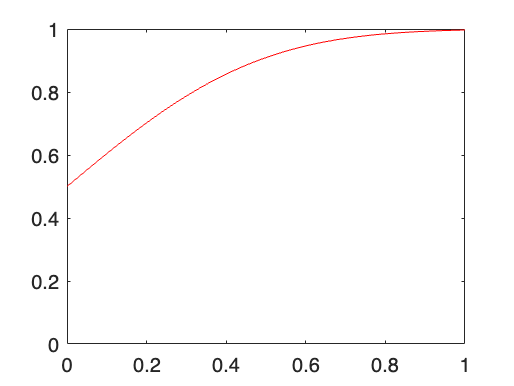

x = 0 : 0.01: 1;

P_D = 1 - 0.5 .* (normcdf(0.5-3.*x)+normcdf(-0.5-3.*x));
plot(x, P_D, 'r'), axis([0 1 0 1])

load hw2dat
% Metal objects: H1
% Wooden objects: H0

% Col 1: data from H0
% Col 2: data from H1
% Col 3: source info for test data
% Col 4: test data
H_0 = hw2dat(:, 1);
H_1 = hw2dat(:, 2);
S_info = hw2dat(:, 3);
test = hw2dat(:, 4);

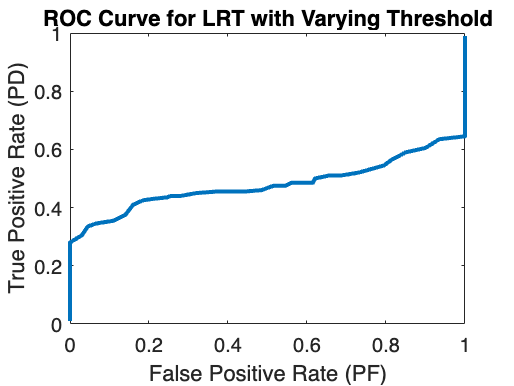

% Select only the first 200 points of H1 and H0 columns
H1 = H_1(1:200);
H0 = H_0(1:200);

% Set up threshold values
thresholds = -4:0.1:4;

% Calculate true positive rate (TPR) and false positive rate (FPR) for each threshold
for i = 1:length(thresholds)
    t = thresholds(i);
    PD(i) = sum(H1 > t) / length(H1);
    PF(i) = sum(H0 > t) / length(H0);
end

% Plot ROC curve
plot(PF, PD, 'LineWidth', 2);
xlabel('False Positive Rate (PF)');
ylabel('True Positive Rate (PD)');
title('ROC Curve for LRT with Varying Threshold');